# **[고급제어이론 및 로봇응용] Practice 01 : OpenManipulator-X 모델 불러오기**

- **작성자** : 박경훈 (서울시립대학교 전자전기컴퓨터공학부)

- **작성일** : 2024. 9. 5. 

Practice 01에서는  교과목에서 주로 다룰 ROBOTIS의 교육용/연구용 4축 로봇 팔인 [OpenManipulator-X](https://emanual.robotis.com/docs/en/platform/openmanipulator_x/overview/)을 `MATLAB` 및 `Simulink` 환경으로 불러오는 작업을 진행해봅니다.

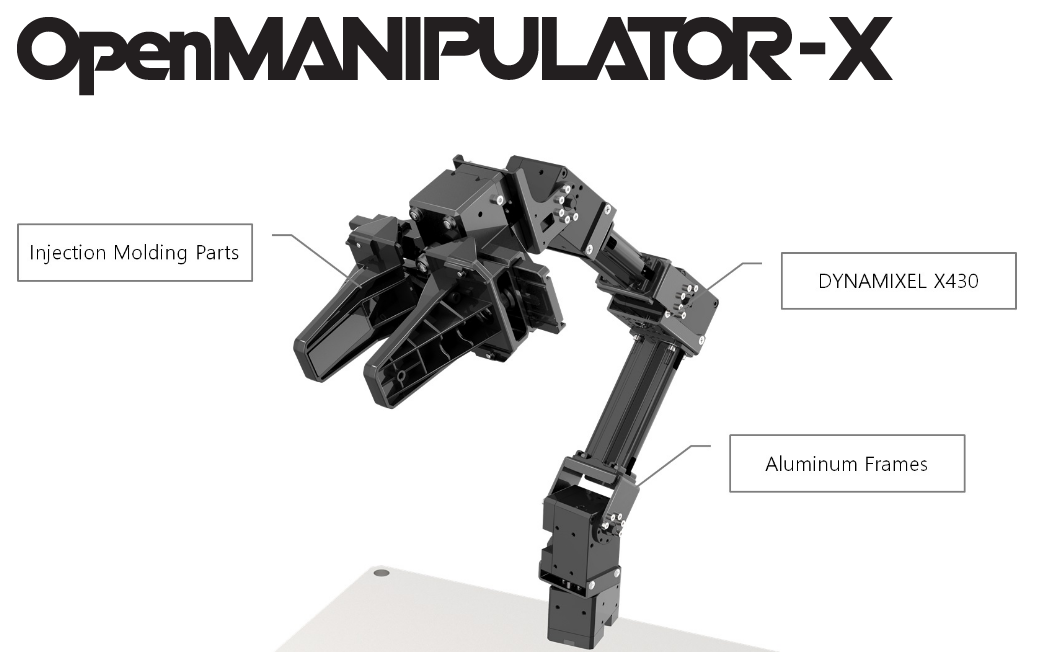

**참고**

- 본 파일을 구동하기 위해서는 `MATLAB 2023b `(혹은 그 이상의 버전), `Simulink`, `Robotics System Toolbox`, `Simscape Multibody` 등이 추가로 필요합니다.

- [`Robotics System Toolbox`](https://kr.mathworks.com/help/robotics/index.html?s_tid=CRUX_lftnav)는 Mathworks에서 공식적으로 제공하는 toolbox로써, P. Corke 교수님이 자체적으로 개발한 [`Robotics Toolbox`](https://petercorke.com/toolboxes/robotics-toolbox/)와는 별개의 toolbox입니다.

## STEP 0 : 초기화

clc;
close all;
clear all;
cd 'C:\github_clone\Course_ACT-RA\P01';

(마지막 줄은, 본인의 파일 경로에 맞게 수정해주세요.)

## **STEP 1 : Xacro file 수정 및 설명**

OpenManipulator-X와 관련된 모델 정보는, ROBOTIS에서 공식적으로 제공하는 git에서 다운로드 받을 수 있습니다. 

[https://github.com/ROBOTIS-GIT/open_manipulator](https://github.com/ROBOTIS-GIT/open_manipulator) 

이 중 `open_manipulator_description` 폴더에 로봇 모델과 관련된 주요 정보들이 나와 있습니다.

- **urdf 폴더** : 로봇의 기구학적, 동역학적 특성을 기술하는 `xacro` 파일이 담겨있습니다. 

- **meshes 폴더** : 시각화와 관련된 `stl` 파일이 담겨있습니다.

여기서 [Xacro](http://wiki.ros.org/xacro)(XML Macros)는 로봇 모델 정보를 기술하는 [URDF](https://wiki.ros.org/urdf)(Unified Robot Description Format)의 확장된 형태로, macro 등의 기능이 추가된 것이 주요 특징입니다.

한편 OpenManipulator-X는 4자유도를 가지는 spatial manipulator로 설계되어 있고, 각 joint의 구동축들이 y 축으로 설정되어 있어서 강의 내용과 차이가 있습니다.

본 강의에서는 3차원 공간에서 제어할 때 발생하는 복잡성을 해소하기 위해, **Xacro 파일을 일부 수정하여 자유도를 제한한 planar manipulator를 다루도록 하겠습니다.**

수정한 결과는 `./model` 폴더에 다음의 Xacro 파일로 각각 저장되어 있습니다.

- `open_manipulator_2DOF_rev.urdf.xacro` : 구동축을 z 축으로 변경하고, Joint 1, Joint 4를 고정합니다. 

- `open_manipulator_3DOF_rev.urdf.xacro`** :** 구동축을 z 축으로 변경하고, Joint 1을 고정합니다.

따라서 위의 Xacro 파일들은, 각각 자유도를 2개 혹은 1개 떨어트린 형태의 OpenManipulator-X 로봇입니다.

## STEP 2 : 로봇 모델을 `rigidBodyTree`로 불러오기

이제 수정한 Xacro 파일을 `importrobot()` 함수를 사용하여 MATLAB/Simulink 환경으로 불러옵니다.

cd ..;
cd '.\model';
myRobot_2dof = importrobot('open_manipulator_2DOF_rev.urdf.xacro');
myRobot_3dof = importrobot('open_manipulator_3DOF_rev.urdf.xacro');
cd ..;
cd 'P01';

위의 두 로봇들은 모두 `Robotics System Toolbox`가 제공하는 데이터형인 [`rigidBodyTree`](https://kr.mathworks.com/help/robotics/ref/rigidbodytree.html)라는 형태로 저장됩니다. 

이후의 작업을 위해 이들의 data format과 gravity vector에 대한 정보들을 재설정해줍니다.

myRobot_2dof.DataFormat = 'column';
myRobot_3dof.DataFormat = 'column';

gravityVec = [0 0 -9.80665];
myRobot_2dof.Gravity = gravityVec;
myRobot_3dof.Gravity = gravityVec;

불러온 로봇들에 대한 정보를 살펴보기 위해 다음 함수들을 활용할 수 있습니다. 

- `show(<rigidBodyTree>) `: 3D 공간 상에서 로봇을 시각화할 수 있습니다.

- `showdetails(<rigidBodyTree>)` : 로봇을 기술하는 tree의 구체적인 정보를 얻을 수 있습니다. 

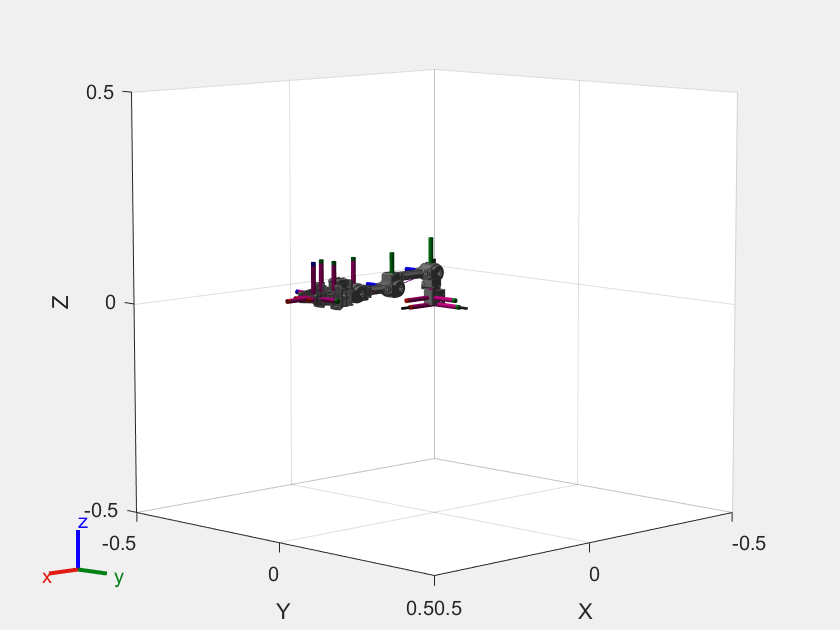

figure("Name","3D Plot of myRobot_2dof");
show(myRobot_2dof); 

showdetails(myRobot_2dof);

--------------------
Robot: (8 bodies)

 Idx                Body Name                Joint Name                Joint Type                Parent Name(Idx)   Children Name(s)
 ---                ---------                ----------                ----------                ----------------   ----------------
   1                    link1               world_fixed                     fixed                        world(0)   link2(2)  
   2                    link2                    joint1                     fixed                        link1(1)   link3(3)  
   3                    link3                    joint2                  revolute                        link2(2)   link4(4)  
   4                    link4                    joint3                  revolute                        link3(3)   link5(5)  
   5                    link5                    joint4                     fixed                        link4(4)   end_effector_link(6)  gripper_link(7)  gripper_link_sub(8)  
   6     

여기서 show() 함수를 통해 시각화한 로봇의 형상(configuration)은, `rigidBodyTree`에 저장되어 있는 homeConfiguration으로 기본 설정되어 있습니다. 

아래 코드를 통해 현재의 homeConfiguration을 얻을 수 있습니다. 

myRobot_2dof.homeConfiguration

ans =      0
     0


만약 다른 형상에 대해 3D plot을 얻고 싶다면, 아래와 같이 진행하면 됩니다. 

**주의** : 지금은 data format을 'column'으로 정의했기 때문에, 로봇과 관련된 모든 vector들을 column vector로 작성해야 합니다.

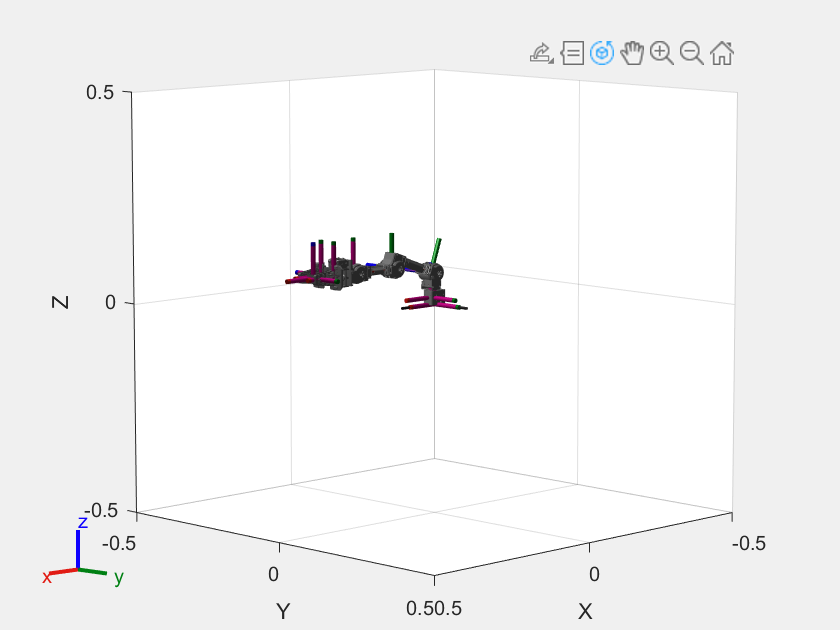

ans =   Axes (Primary) - 속성 있음:

             XLim: [-0.5000 0.5000]
             YLim: [-0.5000 0.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  모든 속성 표시


figure("Name","3D Plot of myRobot_3dof (at the configuration [pi/9;pi/9])");
show(myRobot_2dof,[pi/9;-pi/9])

## **STEP 3 : **`rigidBodyTree`**에서 로봇의 끝점 정보 얻기**

Robotics Systems Toolbox에서는 `rigidBodyTree`로 저장된 로봇을 구성하는 frame들 간의 homogeneous transformation 계산을 함수로써 제공합니다.

예를 들어 homeConfiguration에서 myRobot_2dof의 끝점의 위치 및 (Euler angle로 변환된) 자세는 다음의 코드를 통해 얻을 수 있습니다. 

eeTransform_homeConfiguration = getTransform(myRobot_2dof, [0;0], 'world', 'end_effector_link')

eeTransform_homeConfiguration =     1.0000         0         0   -0.3900
         0    1.0000         0    0.0000
         0         0    1.0000   -0.0525
         0         0         0    1.0000


eePos_homeConfiguration = tform2trvec(eeTransform_homeConfiguration)

eePos_homeConfiguration =    -0.3900    0.0000   -0.0525


eeEul_homeConfiguration = tform2eul(eeTransform_homeConfiguration)

eeEul_homeConfiguration =      0     0     0


만약 $(\theta_1,\theta_2)=(\pi/9, -\pi/9)$일 때의 end-effector의 위치 및 자세는 다음과 같이 다시 얻을 수 있습니다. 

eeTransform_newConfiguration = getTransform(myRobot_2dof, [pi/9;-pi/9], 'world', 'end_effector_link')

eeTransform_newConfiguration =     1.0000    0.0000         0   -0.3905
         0    1.0000         0   -0.0000
         0         0    1.0000   -0.0977
         0         0         0    1.0000


eePos_newConfiguration = tform2trvec(eeTransform_newConfiguration)

eePos_newConfiguration =    -0.3905   -0.0000   -0.0977


eeEul_newConfiguration = tform2eul(eeTransform_newConfiguration)

eeEul_newConfiguration =      0     0     0


**주의** : 위의 값들은 world frame을 기준으로 계산되었음에 주의합시다. 

## STEP 4 : Simulink 환경에서 Simscape 기반 시뮬레이션하기

시간 영역에서의 시뮬레이션을 진행하기 위해, 위의 Xacro 혹은 `rigidBodyTree `모델을 Simulink로 불러올 필요가 있습니다. 

이를 위해 Robotics Systems Toolbox에서는 `smimport() `함수를 제공합니다.

smimport(myRobot_2dof);

위의 코드를 실행시키면, 다음과 같은 형태의 블록들이 Simulink 환경에서 자동으로 생성됨을 확인할 수 있습니다. 

(해당 결과는 `./sim/sim_myRobot_2dof_wo_input.slx에` 저장되어 있습니다.)

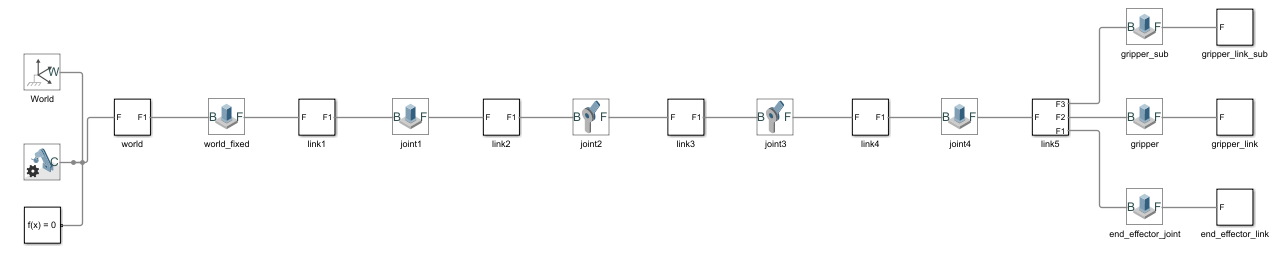

위는 `Simscape Multibody`의 구성요소들을 자동으로 결합하여 `myRobot_2dof`를  Simulink 환경에서 구현한 것입니다. 

이를 구동함으로써 로봇의 동적 시뮬레이션이 가능해집니다. 

cd ..;
cd '.\sim';
sim('sim_myRobot_2dof_wo_input.slx');

이를 구동하면 아래와 같이 중력에 의해 낭창하게 흔들리는(...) 로봇을 확인해볼 수 있습니다. 

딱히 잘못한 것은 아니고, 아직 제어 입력을 넣지 않았기 때문입니다. 제어 입력을 넣는 방식에 대해서는 다음 시간에 좀 더 자세히 살펴보도록 하겠습니다.